clc;
clear;

## Q1a: Exact Interpolation Method

% generate training data:
rng(30);  % For reproducibility
x_train = -1.6:0.08:1.6;
y_train = 1.2*sin(pi*x_train)-cos(2.4*pi*x_train)+0.3*randn(size(x_train));

% compute RBF matrix:
sigma = 0.1;
centers = x_train; % number of hidden units = number of data points
Phi = exp(-pdist2(x_train', centers').^2/(2*sigma^2));

% solve the weights:
w = Phi\y_train'; % exact interpolation (Φ * w = y_train), w = Φ^(-1)*y_train

% test set evaluation:
x_test = -1.6:0.01:1.6;
Phi_test = exp(-pdist2(x_test', centers').^2/(2*sigma^2));
y_pred = Phi_test * w;
test_mse = mean((y_pred - (1.2*sin(pi*x_test) - cos(2.4*pi*x_test))').^2)

test_mse = 0.0690

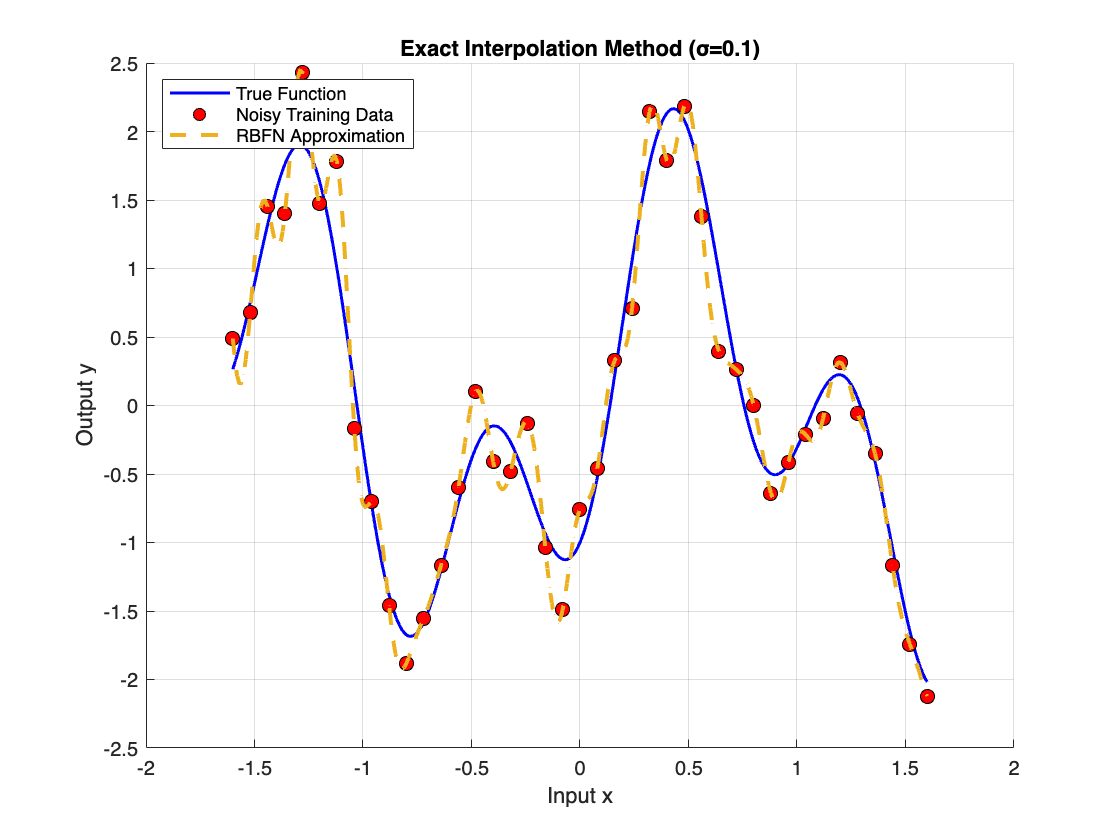

% Visualization
figure('Name','Q1a: Exact Interpolation');
hold on;

% Generate true function values
x_true = -1.6:0.01:1.6;
y_true = 1.2*sin(pi*x_true) - cos(2.4*pi*x_true);

% Plot true function
plot(x_true, y_true, 'b-', 'LineWidth', 1.5, 'DisplayName','True Function'); 

% Plot noisy training data
scatter(x_train, y_train, 50, 'filled', 'MarkerEdgeColor','k',...
    'MarkerFaceColor','r', 'DisplayName','Noisy Training Data');

% Plot RBFN approximation
plot(x_test, y_pred, '--', 'LineWidth', 2, 'DisplayName','RBFN Approximation');

title('Exact Interpolation Method (σ=0.1)');
xlabel('Input x'); ylabel('Output y');
legend('Location','NorthWest');
grid on;
hold off;

## Q1b: Fixed Centers Selected at Random

% randomly select 20 centers:
M = 20;
idx = randperm(length(x_train), M);
centers_random = x_train(idx);

% calculate pairwise distances between centers:
pairwise_dist = pdist(centers_random');

% find maximum distance between centers:
d_max = max(pairwise_dist);

% compute sigma using d_max:
sigma = d_max/sqrt(2*M);

% compute RBF matrix:
Phi_rand = exp(-pdist2(x_train', centers_random').^2 / (2*sigma^2));

% solve for weights (Least Square):
w_rand = Phi_rand \ y_train';

% test set evaluation:
Phi_test_rand = exp(-pdist2(x_test', centers_random').^2 / (2*sigma^2));
y_pred_rand = Phi_test_rand * w_rand;
test_mse_rand = mean((y_pred_rand - (1.2*sin(pi*x_test) - cos(2.4*pi*x_test))').^2)

test_mse_rand = 0.0148

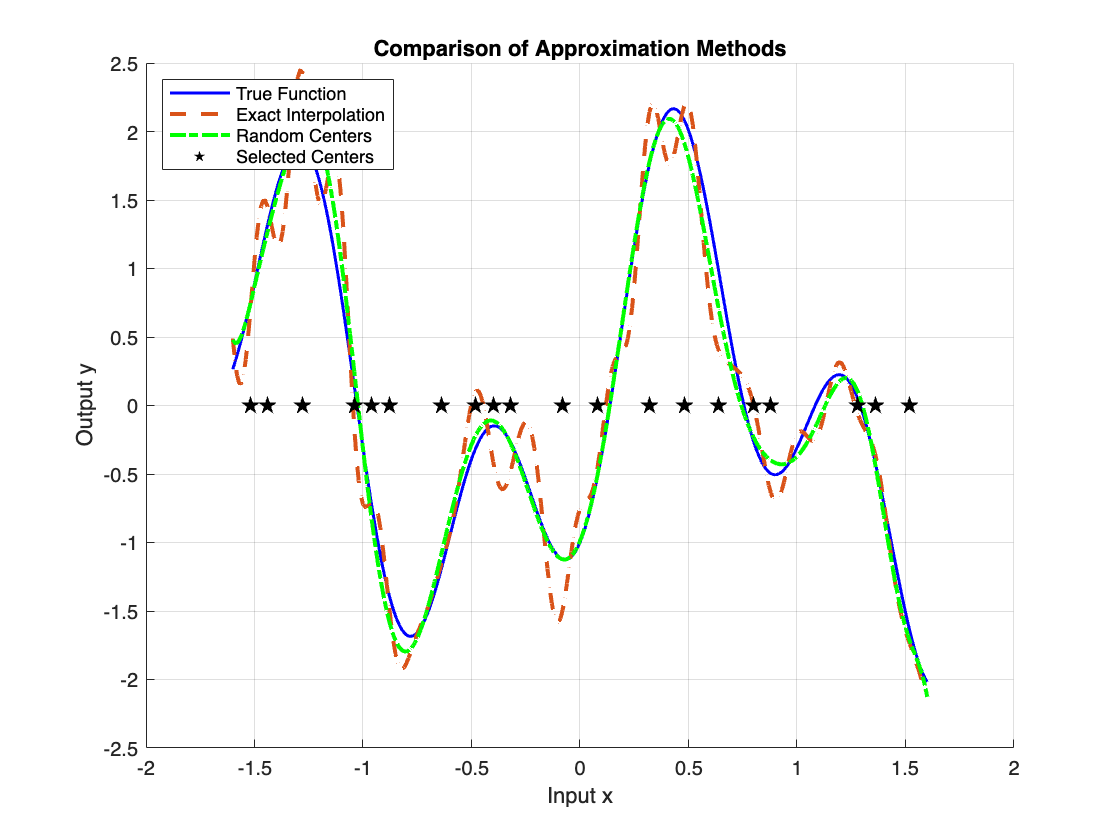

% Visualization:
figure('Name','Q1b: Fixed Centers Comparison');
hold on;

% Plot true function
plot(x_true, y_true, 'b-', 'LineWidth', 1.5, 'DisplayName','True Function');

% Plot both approximations
plot(x_test, y_pred, '--', 'LineWidth', 2, 'DisplayName','Exact Interpolation');
plot(x_test, y_pred_rand, 'g-.', 'LineWidth', 2, 'DisplayName','Random Centers');

% Highlight random centers
scatter(centers_random, zeros(size(centers_random)), 100, 'kpentagram',...
    'filled', 'DisplayName','Selected Centers');

title('Comparison of Approximation Methods');
xlabel('Input x'); ylabel('Output y'); 
legend('Location','NorthWest');
grid on;
hold off;

## Q1c: Regularization Method

% Regularization factors
lambda_values = [0, 1e-4, 1e-2, 0.1, 1, 10];  
test_mses = zeros(size(lambda_values));
y_pred_reg_res = {};

% precompute Phi' * Phi, Phi' * y_train'
term1 = Phi' * Phi;
term2 = Phi' * y_train';

% w = (Phi'*Phi+lambda*I)\(Phi'*d)
for i = 1:length(lambda_values)
    lambda = lambda_values(i);
    w_reg = (term1 + lambda * eye(size(Phi,2))) \ (term2);
    y_pred_reg = Phi_test * w_reg;
    y_pred_reg_res{i} = y_pred_reg;
    test_mses(i) = mean((y_pred_reg - (1.2*sin(pi*x_test) - cos(2.4*pi*x_test))').^2);
    fprintf("λ=%f, MSE=%f\n", lambda, test_mses(i));
end

λ=0.000000, MSE=0.069025
λ=0.000100, MSE=0.046681
λ=0.010000, MSE=0.028548
λ=0.100000, MSE=0.019423
λ=1.000000, MSE=0.028384
λ=10.000000, MSE=0.429659


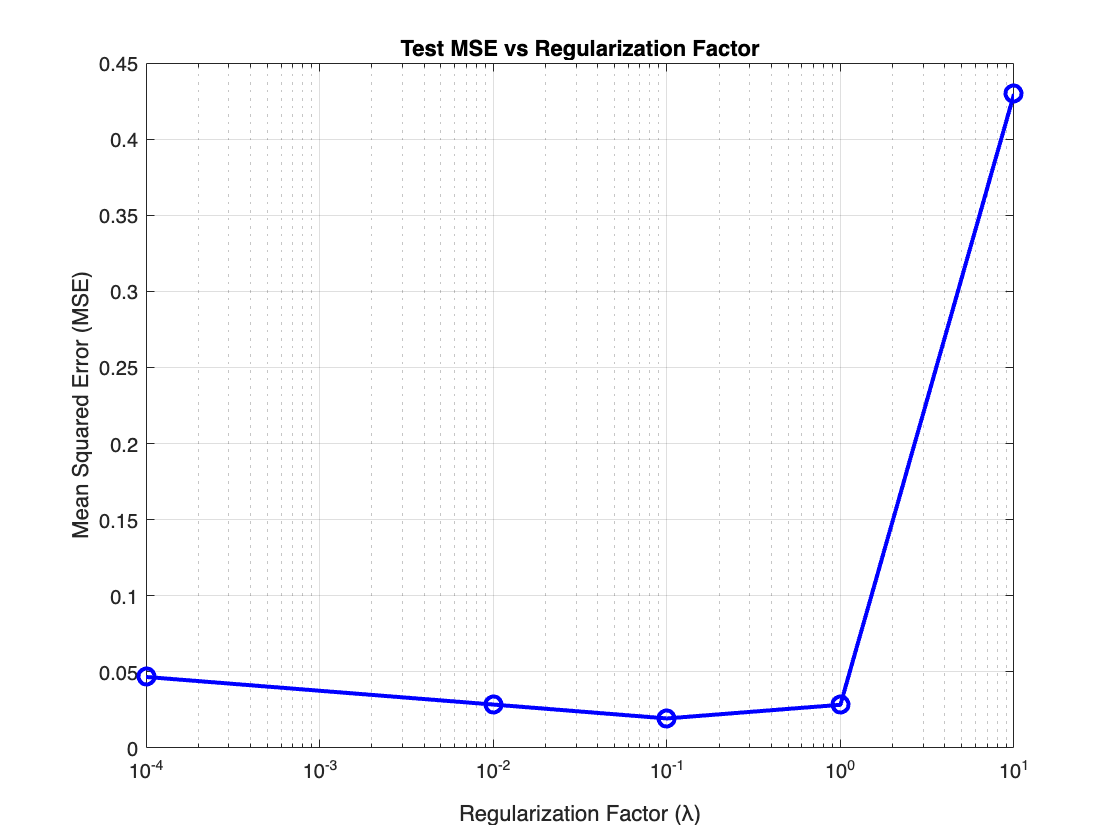

% Visualization
figure('Name','Q1c: Regularization MSE');
semilogx(lambda_values, test_mses, 'bo-', 'LineWidth', 2, 'MarkerSize', 8);
title('Test MSE vs Regularization Factor');
xlabel('Regularization Factor (λ)'); 
ylabel('Mean Squared Error (MSE)');
grid on;

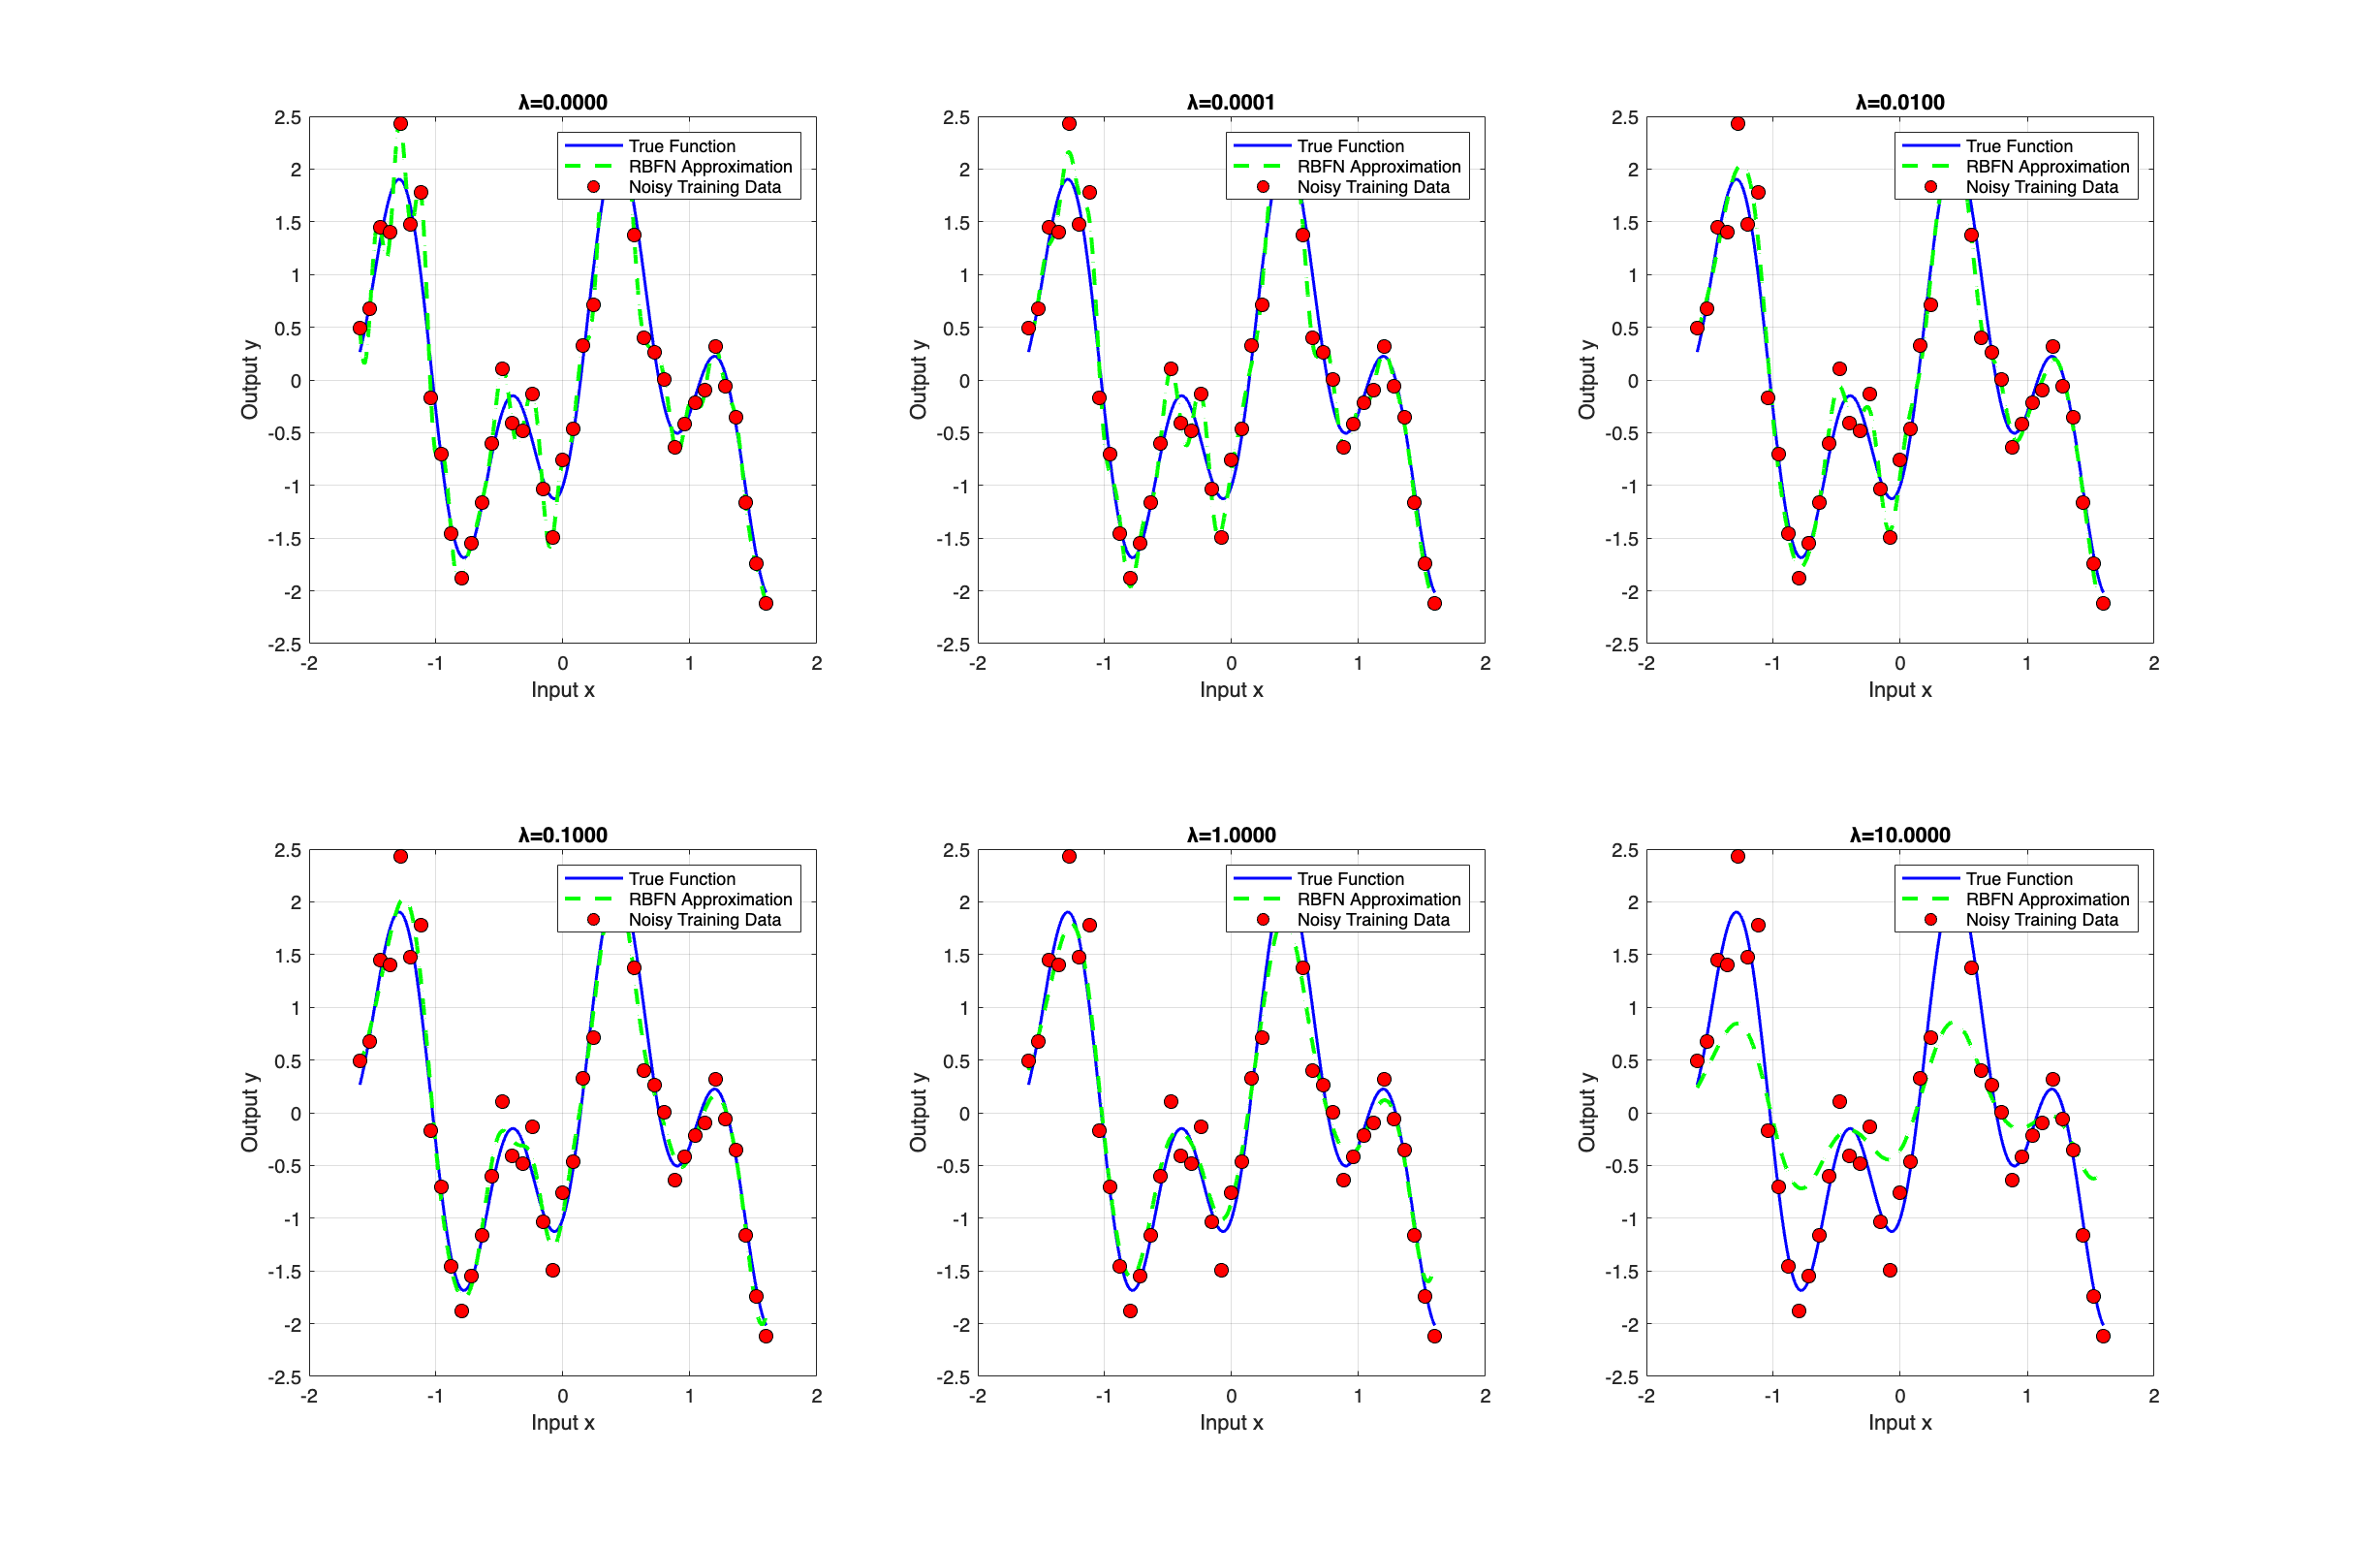

% Fitting results
fig1 = figure('Name',"RBFN Approximation (Regularization Method)");
screensize = get(0, 'screensize');
set(gcf, 'position', screensize);

for i = 1:length(lambda_values)
    subplot(2, 3, i);
    % Plot ground truth vs predictions
    plot(x_true, y_true, 'b-', 'LineWidth', 1.5, 'DisplayName','True Function');hold on;
    plot(x_test, y_pred_reg_res{i}, 'g--', 'LineWidth', 2, 'DisplayName','RBFN Approximation');
    scatter(x_train, y_train, 50, 'filled', 'MarkerEdgeColor','k',...
    'MarkerFaceColor','r', 'DisplayName','Noisy Training Data');

    % Figure formatting
    title(sprintf('λ=%.4f', lambda_values(i)));
    xlabel('Input x'); ylabel('Output y');
    legend('Location','northeast');
    grid on;
    hold off;
end